# Ex1

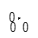

clearvars
close all
clc

[P, F] = seixos3();

patch('Vertices', P(1:3,:)', 'Faces', F, 'FaceColor', 'g')
axis([-1 6 -1 6 -1 6])
xlabel('X'), ylabel('Y'), zlabel('Z')
axis square
grid on

view(135,20)

% A ordem em que as transformações são feitas importa
T1 = trans(0,0,5)*rotx(-pi/2);
%T1 = rotx(-pi/2)*trans(0,-5,0);

P1 = T1*P;
patch('Vertices', P1(1:3,:)', 'Faces', F, 'FaceColor', 'b')

T2 = T1*trans(0,0,4)*roty(pi/2);

P2 = T2*P;
patch('Vertices', P2(1:3,:)', 'Faces', F, 'FaceColor', 'b')

T3 = T2*trans(0,0,4)*rotx(-pi/2);

P3 = T3*P;
patch('Vertices', P3(1:3,:)', 'Faces', F, 'FaceColor', 'b')

T4 = T3*trans(0,0,5)*roty(pi/2);

P4 = T4*P;
patch('Vertices', P4(1:3,:)', 'Faces', F, 'FaceColor', 'b')

T5 = T4*trans(0,0,4)*rotx(-pi/2);

P5 = T5*P;
patch('Vertices', P5(1:3,:)', 'Faces', F, 'FaceColor', 'b')

## Exercício 5

clearvars
close all
clc

[P, F] = seixos3();

h = patch('Vertices', P(1:3,:)', 'Faces', F, 'FaceColor', 'g');
axis([-1 6 -1 6 -1 6])
xlabel('X'), ylabel('Y'), zlabel('Z')
axis square
grid on

view(135,20)

NN=10;
T(:,:,:,1) = mtrans(0,0,linspace(0,5,NN));
T(:,:,:,2) = mrotx(linspace(0,-pi/2,NN));
T(:,:,:,3) = mtrans(0,linspace(0,6,NN),0);
T(:,:,:,4) = mroty(linspace(0,pi/2,NN));
T(:,:,:,5) = mtrans(linspace(0,4,NN),0,0);
T(:,:,:,6) = mrotx(linspace(0,-pi/2,NN));

order=[0 1 0 1 0 1];
Tcurr=eye(4,4);

for n=1:size(T,4)
    Tcurr = manimate(h,P,Tcurr, T(:,:,:,n), order(n));
    pause(1)
end